clear all; close all; clc;

Scegliere un valore per AR:

AR =8;
S=100;
b=sqrt(S*AR);

Scegliere un valore per il rapporto di rastremazione:

lampda =0.4;
c_r=5;
c_t=lampda*c_r;

Scegliere un valore per l'angolo di freccia:

Sigma_le =20;

Scegliere un valore per l'angolo di diedro:

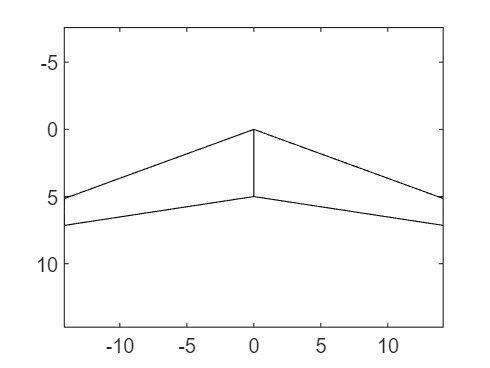

gamma =4;
x_0=[0,0];
y_0=[0,c_r];
c=b/2*tan(Sigma_le*pi/180);
h=b/2*tan(gamma*pi/180);
x_1=[0,b/2];
y_1=[0,c];
x_2=[b/2,b/2];
y_2=[c,c+c_t];
x_3=[0,b/2];
y_3=[c_r,c+c_t];
x_4=[0,b/2];
y_4=[0,h];
plot(x_0,y_0,'k'); hold on; plot(x_1,y_1,'k',-x_1,y_1,'k'); plot(x_2,y_2,'k',-x_2,y_2,'k');plot(x_3,y_3,'k',-x_3,y_3,'k'); axis("ij"); hold off;
axis equal

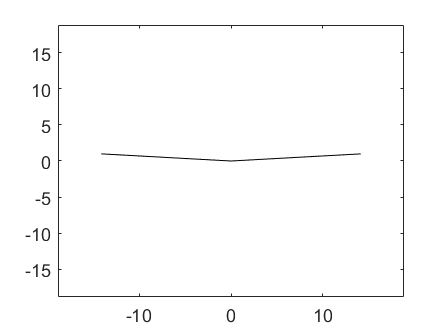

plot(x_4,y_4,'k'); hold on; plot(-x_4,y_4,'k');hold off; axis([-b/1.5 b/1.5 -b/1.5 b/1.5]);

if AR<4
kp            = 1 + AR*(1.87 - 0.000233*Sigma_le)/100;
else
kp            = 1 + ((8.2 - 2.3*Sigma_le)- AR*(0.22 - 0.153*Sigma_le))/100;  
end
Cl_a          = 2*pi*AR/(2 + sqrt(4 + (AR^2/(kp^2))*(1 + (tan(Sigma_le*pi/180) - 2*(1 - lampda)/(AR*(1 + lampda)))^2)));
CL_beta       = -(Sigma_le*pi/(180*6))*Cl_a*(1+2*lampda)/(1+lampda);
CL_beta_sigma = -1/3*sin(2*Sigma_le*pi/180)*(1+2*lampda)/(1+lampda);
c_bar         = 2/3*c_r*(1 + lampda + lampda^2)/(1+lampda);
Y_c_bar       = b/6*(1+2*lampda)/(1+lampda);
Xle_c         = Y_c_bar*tan(Sigma_le*pi/180);
TanS_c_4      = tan(Sigma_le*pi/180) - 2*(1 - lampda)/(AR*(1 + lampda));
Cn_beta       = 1/57.3 * (1/(4*pi*AR) - (TanS_c_4/(pi*AR*(AR+4*cos(atan(TanS_c_4)))))*(cos(atan(TanS_c_4)) - AR/2 - AR*AR/(8*cos(atan(TanS_c_4))) + 6*Xle_c/c_bar*sin(atan(TanS_c_4))/AR));

s.sref = S;
s.cbarr = c_bar;
s.blref = b;
s.croot = c_r;
s.ctip = c_t;
s.semispan = b/2;
s.expsemispan = b/2;
s.sweep = Sigma_le/57.3;
s.sweepx = 0;
s.twist = 0;
s.dihedral = gamma/57.3;

[xac, wing] = datcomXac(s);

Writing DATCOM input file...


DATCOM input file written into: myWing.dcm
Executing DATCOM for myWing
 
*============================================================================= 
*  Main program for DATCOM-MODELER 
* 
*  Copyright (C) 2009  Anders Gidenstam (anders(at)gidenstam.org) 
*  Copyright (C) 2009  Ronald Jensen    (ron(at)jentronics.com) 
*  http://www.gidenstam.org 
*  http://www.jentronics.com 
* 
*  This program is free software; you can redistribute it and/or modify 
*  it under the terms of the GNU General Public License as published by 
*  the Free Software Foundation; either version 3 of the License, or 
*  (at your option) any later version. 
* 
*  This program is distributed in the hope that it will be useful, 
*  but WITHOUT ANY WARRANTY; without even the implied warranty of 
*  MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the 
*  GNU General Public License for more details. 
* 
Creating file: myWing.2.ac
   Running PREDAT 
 File opened : myWing.dcm
 
   Running DATCOM+ 
. 
 
   

END



disp(['x_ac/c = ',num2str(xac)])

x_ac/c = 0.46887
